- Load Audio

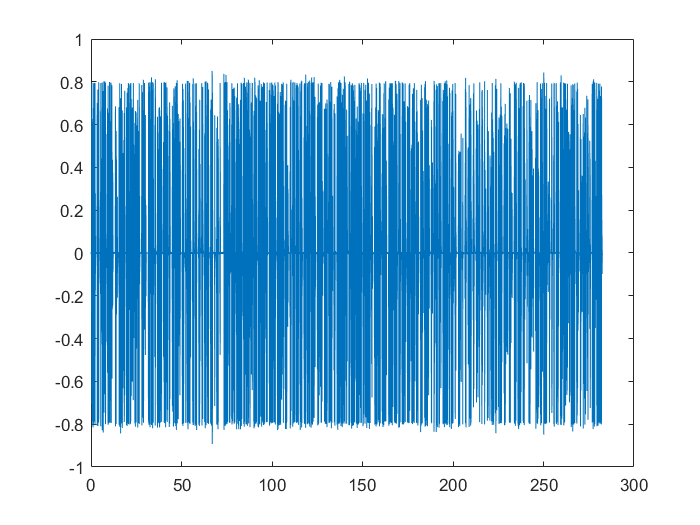

[orig_audio, orig_Fs] = audioread("audio_sample_2.mp3");
% downsample_ratio = 1;
% orig_audio = downsample(orig_audio, orig_Fs / downsample_ratio);
% orig_Fs = orig_Fs / downsample_ratio;
t = (1/orig_Fs) * (0:length(orig_audio)-1);
plot(t, orig_audio);

2. Generating Noise

% Adding noise
[noise_sample, noise_Fs] = audioread("noise_sample_4-blue_noise.wav")

noise_sample =          0
   -0.0050
   -0.0027
    0.0071
    0.0222
    0.0178
   -0.0002
   -0.0405
    0.0462
    0.0014


noise_Fs = 44100

% noisy_audio = awgn(orig_audio, 25);
% sound(noisy_audio, orig_Fs)
% noise_sample = downsample(noise_sample, orig_Fs);

% 
if numel(noise_sample(:,1)) > numel(orig_audio)
    rand_noise_index = randi(abs(numel(noise_sample(:,1)) - numel(orig_audio)) + 1, 1, 1);
    gen_noise = noise_sample(rand_noise_index:rand_noise_index + numel(orig_audio) - 1);
else
    orig_audio = orig_audio(1:length(noise_sample));
    gen_noise = noise_sample(:,1);
    gen_noise = gen_noise';
    t = t(1:length(noise_sample));
end

% Correlated recording of environmental noise
noise_ref_mic_ratio = 1.2 % Simulate more "realistic" setup

noise_ref_mic_ratio = 1.2000

%Apply FIR filter to ensure correlation between noise and recording
firfilt = dsp.FIRFilter;
firfilt.Numerator = fir1(11,0.4);
f_noise = firfilt(gen_noise * noise_ref_mic_ratio)

f_noise =          0   -0.0000   -0.0000    0.0000    0.0001    0.0001   -0.0000   -0.0001    0.0002    0.0000   -0.0003    0.0002    0.0001   -0.0002   -0.0002    0.0001    0.0000    0.0002   -0.0002   -0.0000    0.0003   -0.0006   -0.0004   -0.0001    0.0000    0.0000    0.0002   -0.0004   -0.0001    0.0004   -0.0006    0.0006   -0.0006    0.0005   -0.0003    0.0004    0.0001   -0.0002   -0.0003   -0.0005    0.0011    0.0005    0.0002    0.0005   -0.0012   -0.0003    0.0010    0.0004    0.0002    0.0002


3. Adding Noise

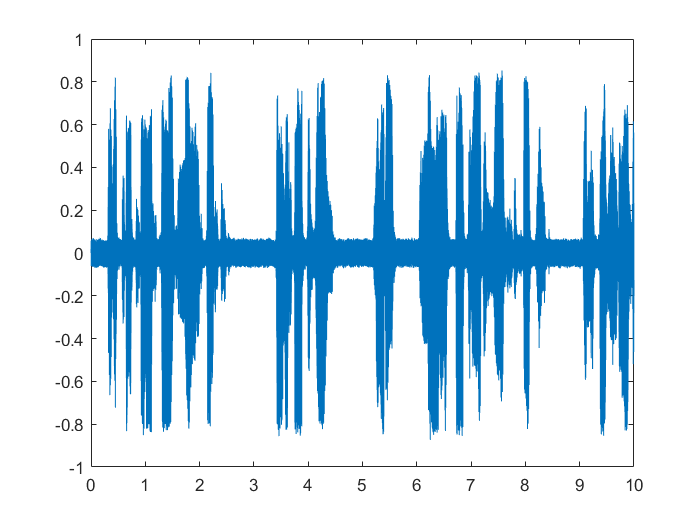

orig_power = sum(orig_audio.^2);
noise_weakness_factor = 30;
noise_power = sum(gen_noise.^2) * noise_weakness_factor;

noisy_audio = orig_audio + sqrt(orig_power/noise_power) * gen_noise';

% Frequency Analysis
% freq_values = fft(noisy_audio);
% noise_len = length(noisy_audio);          % number of samples
% f = (0:noise_len-1)*(orig_Fs/noise_len);     % frequency range
% power = abs(freq_values).^2/noise_len;
% plot(f, power)
% % sound(noisy_audio, orig_Fs);
% % sound(f_noise', orig_Fs)
% plot(t, f_noise);
plot(t, noisy_audio)

sound(noisy_audio, orig_Fs);


4. LMS Noise Cancellation (Custom feature that requires noise reference (e.g. second mic))

% aaa
use_lms = true

use_lms = logical
   1


use_lms_only = false

use_lms_only = logical
   0


if use_lms

    initial_coefficents = (firfilt.Numerator).'-0.01;
    step = 0.001; 
    lms = dsp.LMSFilter(12,'Method','Sign-Sign LMS',...
       'StepSize',step,'InitialConditions',initial_coefficents);
    % sound(noisy_audio, orig_Fs)
    [~, noisy_audio] = lms(f_noise', noisy_audio);
    sound(noisy_audio, orig_Fs)
end

5. Butterworth Bandpass Filter

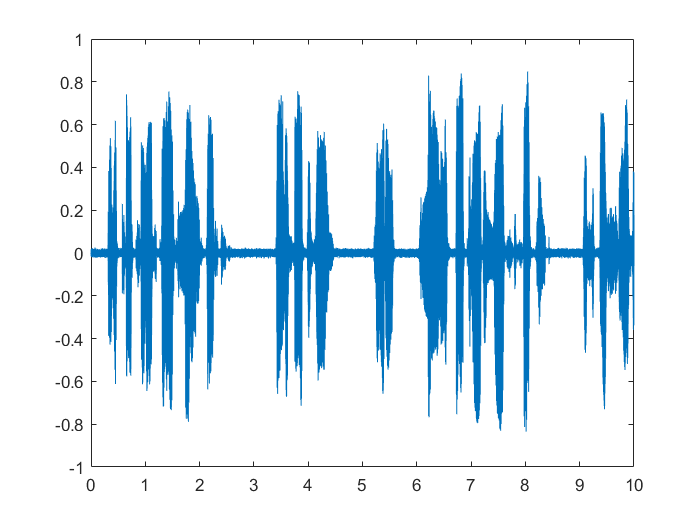

lower_freq = 200;
upper_freq = 4500;
% plot()
[b,a] = butter(5, [lower_freq,upper_freq] / (orig_Fs/2), "bandpass");
butter_audio = filter(b,a,noisy_audio);
plot(t, butter_audio)

sound(butter_audio, orig_Fs)


6. Kaizer FIR Filter

% 
Fs = orig_Fs;  % Sampling Frequency

Fstop1 = 200;      % First Stopband Frequency
Fpass1 = 300;      % First Passband Frequency
Fpass2 = 4500;     % Second Passband Frequency
Fstop2 = 4550;     % Second Stopband Frequency
Dstop1 = 0.001;    % First Stopband Attenuation
Dpass  = 0.1;      % Passband Ripple
Dstop2 = 0.001;    % Second Stopband Attenuation
flag   = 'scale';  % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop1 Fpass1 Fpass2 Fstop2]/(Fs/2), [0 ...
                             1 0], [Dstop1 Dpass Dstop2]);

% Calculate the coefficients using the FIR1 function.
b  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
Hd = dfilt.dffir(b);
kaiser_audio = filter(b,1,butter_audio);
% fzv = linspace(0, 1, 1000)*(Fs/2);                                          % Frequency Vector
% freqz(b, 1024, fzv, Fs)      
sound(kaiser_audio, orig_Fs);

7. Savitzky-Golay Filter (Smoothen)

order = 9;
frame_len = 39;
sgolay_audio = sgolayfilt(kaiser_audio, order, frame_len);
sound(sgolay_audio, orig_Fs);


8. Gaussian Filter

% median_audio = medfilt1(sgolay_audio,10);
% sound(sgolay_audio, orig_Fs);
gaussian_filter = gausswin(3);
gaussian_audio = filter(gaussian_filter, 1, sgolay_audio);
sound(gaussian_audio, orig_Fs);